# CREATING SPECTROGRAM IMAGES AND CORRESPONDING LABELS

This LiveScript generates labeled spectrogram images as simulated data for training neural networks in signal classification tasks. It is implemented to support both CPU and GPU execution.

In particular,** creatingTrainingImages(numFrame, signalLabels, sr, imageSize, useGPU, wantInterf, wantPlot) **function generates 'numFrame' labeled spectrogram images for the given signal label (e.g., 'WLAN', 'ZigBee', 'Bluetooth') using a given sampling rate 'sr' and desired image dimensions 'imageSize'. The images and their label masks are saved into subfolders under 'trainingImages'.

The input values for the function are:

- ** numFrame** - (integer) Number of images (frames) to generate.

-  **signalLabels** - (string) Label of the signal class to generate.

-  **sr** - (double) Sampling rate in Hz.

-  **imageSize** - (cell) Cell array with image size, e.g., {[1024, 1024]}.

-  **useGPU** - (logical) True to use GPU acceleration, false for CPU only.

-  **wantInterf** - (logical) True if the spectrograms should contain interferent signals

-  **wantPlot  **- (logical) True if the spectrograms should be shown

The output values:

- **None**. The function saves image files to disk.

Each signal combination is assigned a unique label value and the table below defines a linear label mapping for five signal types using a bitmask representation. 

- **Bitmask**: Integer value representing the signal type.

- **Signal Combination**: The type of wireless signal present.

- **Label**: The numeric label assigned to the signal, used for classification purposes.

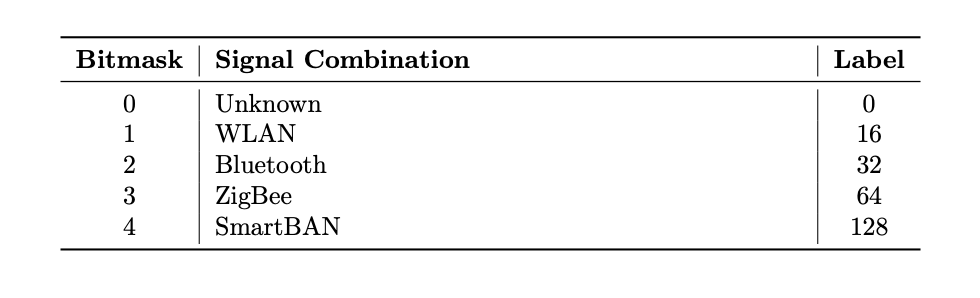

function creatingTrainingImages(numFrame, signalLabels, sr, imageSize, useGPU, wantInterf, wantPlot)

% Set default value for useGPU if not provided
    if nargin < 6
        useGPU = false;
    end
    
    % Check GPU availability if requested
    if useGPU
        try
            gpuDevice();
            fprintf('GPU processing enabled.\n');
        catch ME
            warning('GPU not available or compatible. Falling back to CPU processing.');
            useGPU = false;
        end
    else
        fprintf('CPU processing enabled.\n');
    end

    close all; 
   

    % Create output directories for each image size
    for index = 1:length(imageSize)
        imgSize = imageSize{index};
        folderName = sprintf('%dx%d', imgSize(1), imgSize(2));
        dirName = fullfile('trainingImages', folderName);
        if ~exist(dirName, 'dir')
            mkdir(dirName);
        end
    end
    

    % Class mixture probabilities: more likely to have 3 signal
    weights = [0.2 0.25 0.3 0.25];  
    possibleCombinations = [1 2 3 4];
    for snr = 0:1:35
        fprintf("Current SNR = %d dB\n", snr);
        idxFrame = 0;
        while idxFrame < numFrame
            idxFrame = idxFrame + 1;
            waveforms = [];
            waveformsClean = [];
    
            % Reset available WLAN frequencies at the start of each frame
            resetWLANFrequencies();
    
            % Randomly select how many signals to mix (1, 2, 3 or 4)
            numSignals = randsample(possibleCombinations, 1, true, weights);
            labels = [];
                    
            % Generate synthetic signals
            for iter = 1:numSignals
                prob = rand(); % 1=ZigBee, 2=WLAN, 3=Bluetooth 4 = SmartBAN
                if prob < 0.25 
                    type_signal = 1;
                end
                if prob < 0.45 && prob >= 0.25
                    type_signal = 2;
                end
                if prob >= 0.45 && prob < 0.7
                    type_signal = 3;
                end
                if prob >= 0.7
                    type_signal = 4;
                end

                [noisyWaveform, wfClean, label] = generateWaveform(type_signal, useGPU);
                labels = cat(1, labels, label);
                waveformsClean = cat(2, waveformsClean, wfClean);
                waveforms = cat(2, waveforms, noisyWaveform);
            end

            % Move to GPU if requested
            if useGPU
                gpuWaveFormsClean = gpuArray(waveformsClean);
            else
                gpuWaveFormsClean = waveformsClean;
            end
    
            % Array of all the label matrices 
            data_tot = [];
            P_rx_arr = [];
            % Generate labeled spectrogram masks
            for i = 1:size(gpuWaveFormsClean, 2)
                label = labels(i, :);
                waveform = gpuWaveFormsClean(:, i);
                [P_matrix, ~, P_rx] = createSpectrogram(waveform, sr, imageSize, useGPU, wantPlot);
                P_rx_arr = cat(1, P_rx_arr, P_rx);
                labeledImage = labellingImage(P_matrix, label, signalLabels, imageSize{1}, useGPU, wantPlot);
                data_tot = cat(3, data_tot, labeledImage);
            end
            [gpuWaveFormsClean, noisePower, pMax] = adjustRxPower(gpuWaveFormsClean, snr, P_rx_arr, labels, useGPU);
            
            % Mix signals and create final spectrogram
            if useGPU
                waveFormsClean = gather(gpuWaveFormsClean);
                pMax = gather(pMax);
            else
                waveFormsClean = gpuWaveFormsClean;
            end
            
            if wantInterf
                mixedSignal = mySignalMixerInterf(waveFormsClean, 20e-3, noisePower, pMax);
            else
                mixedSignal = mySignalMixer(waveFormsClean, 20e-3, noisePower);
            end
            
            if useGPU
                gpuMixedSignal = gpuArray(mixedSignal);
            else
                gpuMixedSignal = mixedSignal;
            end
            
            [~, spectrogramTot] = createSpectrogram(gpuMixedSignal, sr, imageSize, useGPU, wantPlot);
            % Save the final spectrogram and mask
            overlapLabelledImages(data_tot, idxFrame, dirName, labels, spectrogramTot, signalLabels, snr, numFrame);
            fprintf("\n\n\n");
            close all
        end
    end
end

**createSpectrogram** is a function that computes the spectrogram of a time-domain waveform and returns it both as a numeric matrix and as an RGB image. The function takes the input waveform and its sampling rate, then calculates the spectrogram, which is represented in decibel (dB) scale. The resulting image is resized to the specified dimensions provided as input.

The inputs to the function are:

- **waveform **- (vector): time-domain signal.

- **sr **- (double value): sampling rate in Hertz.

- **imageSize ** - (cell): target size of the output image (height and width).

- **useGPU **- (logical): whether GPU acceleration is enabled (true) or if the computation runs on CPU only (false).

The function outputs two results:

- **P **- (matrix): spectrogram matrix in dB scale.

- **I **- (image): the RGB image representation of the spectrogram, resized to the desired dimensions.

function [P, I, P_rx] = createSpectrogram(waveform, sr, imageSize, useGPU, wantPlot)

 % Set default value for useGPU if not provided
    if nargin < 5
        useGPU = false;
    end

    % Declare the fixed scale
    db_min = -130;
    db_max = -50;
    Nfft = 4096;
    window = hann(256);
    overlap = 100;
    colormap_resolution = 256;

    % Move data to appropriate processing unit
    if useGPU && ~isa(waveform, 'gpuArray')
        waveform = gpuArray(waveform);
    elseif ~useGPU && isa(waveform, 'gpuArray')
        waveform = gather(waveform);
    end

    P_rx = 10*log10(max(abs(waveform).^2));

    [~, ~, ~, P] = spectrogram(waveform, window, overlap, Nfft, sr, 'centered', 'psd');
    
    P = 10 * log10(abs(P') + eps);  % Conversione in dB
   
    % Clipping of outliers
    P_db_clipped = min(max(P, db_min), db_max);
    
    % Normalization with respect to the fixed scale
    P_norm = (P_db_clipped - db_min) / (db_max - db_min);
    
    % Ensure data is on CPU for image processing
    if isa(P_norm, 'gpuArray')
        P_norm = gather(P_norm);
    end
    
    % Mapping on a 256-value gray scale
    im = imresize(im2uint8(P_norm), imageSize{1}, "nearest");

    % Convert the image in RGB form
    I = im2uint8(flipud(ind2rgb(im, parula(colormap_resolution))));  % RGB flip

    % Ensure P is on the same processing unit as the input
    if useGPU && ~isa(P, 'gpuArray')
        P = gpuArray(P);
    elseif ~useGPU && isa(P, 'gpuArray')
        P = gather(P);
    end

    if wantPlot
        %for debug
        figure;
        imshow(I);  % for debug
        colormap(parula(colormap_resolution));
        colorbar('Ticks', linspace(0,1,8), ...
                 'TickLabels', linspace(db_min, db_max, 8));  % scale colorbar to dB range
        title('Power (dB)');
        axis image off;
    end

end

**labellingImage** is a function that generates a binary mask for a specific signal within a spectrogram. It takes the input spectrogram in decibel scale and applies thresholding to locate the presence of the target signal. Once the signal region is identified, the function fills its bounding box and assigns an intensity value corresponding to the signal type.

The inputs to the function are:

- **P_dB **- (matrix): spectrogram in decibel scale.

- **label **- (string): signal type (for example, 'ZigBee', 'WLAN', etc.).

- **signalLabels** - (map): associates each signal label with a specific pixel intensity value.

- **imageSize **- (vector): size of the output mask image.

- **useGPU **- (logical): whether GPU acceleration should be used (true) or if the processing should be done on CPU only (false).

The function outputs:

- **data ** - (matrix): represents the binary mask, where regions corresponding to the labeled signal are marked with their respective intensity values.

function data = labellingImage(P_dB, label, signalLabels, imageSize, useGPU, wantPlot)

 % Set default value for useGPU if not provided
    if nargin < 5
        useGPU = false;
    end

    % Ensure data is on CPU for image processing operations
    if isa(P_dB, 'gpuArray')
        P_dB_cpu = gather(P_dB);
    else
        P_dB_cpu = P_dB;
    end

    if strcmp(label, "SmartBAN")
        threshold = max(P_dB_cpu(:)) - 28;
    else
        threshold = max(P_dB_cpu(:)) - 15;
    end
    
    mask = P_dB_cpu >= threshold;
    mask = flipud(mask);  % Align with spectrogram
    cc = bwconncomp(mask);  % Find connected regions

    % Fill bounding boxes around each component
    for i = 1:cc.NumObjects
        [r, c] = ind2sub(size(mask), cc.PixelIdxList{i});
        rmin = min(r); rmax = max(r);
        cmin = min(c); cmax = max(c);
        mask(rmin:rmax, cmin:cmax) = true;
    end

    data = zeros(size(P_dB_cpu));
    pixelValue = signalLabels(label);
    data(mask) = pixelValue;
    
    data = imresize(data, imageSize, "nearest");

    % Move result back to GPU if requested and input was on GPU
    if useGPU && isa(P_dB, 'gpuArray')
        data = gpuArray(data);
    end

    if wantPlot
        im = imresize(im2uint8(rescale(data)), imageSize, "nearest");
        figure;
        imshow(im);
        title('Spectrogram Mask');
    end
end

**overlapLabelledImages** is a function designed to assign unique label values to pixels based on a predefined priority order, ensuring that overlapping signal regions are handled correctly. Each pixel in the output mask is assigned to a single class according to the priority:

**Bluetooth (BT) > SmartBAN > ZigBee > WLAN > AWGN (0)**

This means that when multiple signals overlap at the same pixel, the label with the highest priority is assigned.

The inputs to the function are:

- **data** - (MxNxL): 3D binary mask of size M-by-N-by-L, where L is the number of labels.

- **idxFrame **- (Integer): current frame index.

- **dir **- (string): output directory where results will be saved.

- **labels **- (cell): array containing the names of the labels, for example, {'WLAN', 'Bluetooth', ...}.

- **spectrogram **- (image): spectrogram image corresponding to the current frame, which will be saved.

- **label_map **- (containers.Map): object mapping label names (e.g., 'WLAN') to their corresponding pixel values (e.g., 16).

The function outputs by saving the final labeled mask (**data_final**, as a uint8 matrix) and the associated spectrogram image to the specified directory:

- **saves **('data_final') and **spectrogram image**

function overlapLabelledImages(data, idxFrame, dir, labels, spectrogram, label_map, snr, numFramesPerSnr)

 % Ensure data is on CPU for processing
    if isa(data, 'gpuArray')
        data = gather(data);
    end

    % Define fixed label values and priorities
    priority_order = {"Bluetooth", "SmartBAN", "ZigBee", "WLAN"};  % from highest to lowest
    
    [M, N, ~] = size(data);
    data_final = zeros(M, N, 'uint8');  % Start with AWGN everywhere (value 0)

    for i = 1:length(priority_order)
        label = priority_order{i};
        idx = find(strcmp(labels, label));
        if ~isempty(idx)
            for ii = 1:numel(idx)
                mask = data(:,:,idx(ii));
                to_assign = (data_final == 0) & (mask ~= 0);  % assign only if not yet labeled
                data_final(to_assign) = label_map(label);
            end
            
        end
    end

    % Save label matrix and spectrogram
    label_combination = strjoin(labels', '+');
    filename = num2str(idxFrame + snr*numFramesPerSnr) + "_" + ...
                        label_combination + "_" + snr + "dB";
    fname = fullfile(dir, filename);
    
    save(char(fname + "_frame.mat"), 'data_final');
    imwrite(spectrogram, char(fname + "_spectrogram.png"));
end

**generateWaveform** is a function that creates synthetic waveforms for one of several predefined signal types. Given an input integer specifying the signal type (1 for ZigBee, 2 for WLAN, 3 for Bluetooth, and 4 for SmartBAN), the function generates both a clean and a noisy version of the corresponding signal. The center frequency and channel model for the signal are randomly selected during the generation process.

The inputs to the function are:

- **numOfSignal** - (integer): One of [1, 2, 3, 4], representing: 1 = ZigBee, 2 = WLAN, 3 = Bluetooth, 4 = SmartBAN

- **useGPU** - (logical): True to use GPU acceleration, false for CPU only.

This functions outputs:

- **noisyWf** - (vector): Signal with noise added.

- **wfFin** - (vector): Clean signal (without noise).

- **label** - (string) : Type of signal generated.

function [noisyWf, wfFin, label] = generateWaveform(numOfSignal, useGPU)

 if nargin < 2
        useGPU = false;
    end

    if ~isscalar(numOfSignal) || ~isnumeric(numOfSignal) || floor(numOfSignal) ~= numOfSignal
        error('Input must be an integer.');
    end
    if numOfSignal < 1 || numOfSignal > 4
        error('Input must be an integer between 1 and 4.');
    end

    switch uint8(numOfSignal)
        case 1  % ZigBee
            
            spc = 4;
            numPackets = randi(3);
            centerFreq = 2405e6 + 5e6 * (randi(16) - 11);
            channelType = randsample({'Rician', 'Rayleigh', 'AWGN'}, 1);
            txPowerArr = [-3, 0, 8]; %in dBm
            weights = [0.15 0.75 0.1];  
            txPower = randsample(txPowerArr, 1, true, weights);
            [noisyWf, wfFin] = myZigbEEHelper(spc, numPackets, centerFreq, channelType{1}, txPower);
            label = "ZigBee";

        case 2  % WLAN
            try
                choosenCF = getStaticWLANFrequency();
                label = "WLAN";
            catch ME
                warning(ME.identifier,'%s', ME.message);
                label = "Unknown";
                return;
            end

            txPower = ((rand()- 1/2)*5) + 20.5; %in dBm [18; 23] dBm
            channelType = randsample({'Rician', 'Rayleigh'}, 1);
            [noisyWf, wfFin] = myWlanHelper(choosenCF, channelType{1}, txPower);

        case 3  % Bluetooth
            channelType = randsample({'Rician', 'Rayleigh'}, 1);
            packetTypes = {'FHS', 'DM1', 'DM3', 'DM5', 'DH1', 'DH3', 'DH5', ...
               'HV1', 'HV2', 'HV3', 'DV', 'AUX1', ...
               'EV3', 'EV4', 'EV5', ...
               '2-DH1', '2-DH3', '2-DH5', '3-DH1', '3-DH3', '3-DH5', ...
               '2-EV3', '2-EV5', '3-EV3', '3-EV5'};
            
            txPowerArr = [0, 4, 20]; %in dBm
            weights = [0.03 0.94 0.03];  
            txPower = randsample(txPowerArr, 1, true, weights);
            packetType = packetTypes{randi(length(packetTypes))};
            [noisyWf, wfFin] = myBluetoothHelper(packetType, channelType{1}, txPower);
            label = "Bluetooth";
        
        case 4  %SmartBAN
            label = "SmartBAN";
            channelType = randsample({'Rician', 'Rayleigh'}, 1);
            centerFrequency = randi([0, 39]) * 2e6;
            centerFrequency = centerFrequency + 2.402e9;
            txPowerArr = [0, 4, 20]; %in dBm
            weights = [0.03 0.94 0.03];    
            txPower = randsample(txPowerArr, 1, true, weights);  %in dBm
            [noisyWf, wfFin] = mySmartBanHelper(channelType{1}, centerFrequency, txPower);
    end
    fprintf("Tx Power of %s: %f dBm\n", label, txPower);
    clearvars -except noisyWf wfFin label txPower
end

**getStaticWLANFrequency** is a function that selects a static WLAN center frequency from a persistent list of available IEEE 802.11 channels. Each time the function is called, it returns one frequency chosen at random from the list and removes that frequency to prevent it from being reused within the same frame.

The input values:

- **None**

The output values:

- **choosenCF** - (integer): chosen Center Frequency

**resetWLANFrequencies** is a function that resets the persistent list of WLAN center frequencies used by **getStaticWLANFrequency**. By clearing this persistent variable, the function restores the full list of available WLAN frequencies. It should be called at the start of each new frame to enable frequency reuse across different frames.

The input values:

- **None**

The output values:

- **None**

function choosenCF = getStaticWLANFrequency()

persistent availableFreq

    % Initialize once
    if isempty(availableFreq)
        availableFreq = [2412e6, 2437e6, 2462e6];
    end

    % Check if empty
    if isempty(availableFreq)
        error('No more WLAN center frequencies available.');
    end

    % Sample one frequency randomly
    idx = randi(length(availableFreq));
    choosenCF = availableFreq(idx);

    % Remove it from the list
    availableFreq(idx) = [];
end

function resetWLANFrequencies()

    clear getStaticWLANFrequency

end

**adjustRxPower** is a function that rescales a collection of received waveforms so that their peak power matches a target signal-to-noise ratio (SNR) relative to a fixed additive white Gaussian noise (AWGN) level.

The inputs to the function are:

- **waveforms **- (matrix): each column represents a complex-valued received signal to be scaled.

- **snr_dB **- (integer): desired SNR expressed in decibels (dB), referenced to the AWGN noise power.

- **P_rx_arr **- (vector): contains received power estimates in dB for each waveform column.

- **labels **- (array): contains signal labels corresponding to each waveform.

- **useGPU **- (logical): determines whether to use GPU acceleration (true) or CPU only (false).

The function outputs:

- **waveforms_scaled** - (matrix): the scaled waveforms after amplitude adjustment.

- **noise_power_lin **(integer): the noise power expressed in linear units consistent with the signals.

- **P_rx_max **- (integer): the peak received power in decibels (dB).

function [waveforms_scaled, noise_power_lin, P_rx_max] = adjustRxPower(waveforms, snr_dB, P_rx_arr, labels, useGPU)

 % Set default value for useGPU if not provided
    if nargin < 5
        useGPU = false;
    end

    % --- Fixed AWGN noise floor -------------------------------------------------
    noise_power_dB  = -30;                       % Noise power in dB (measured with Adalm-Pluto @ 60dB gain)
    noise_power_lin = 10^(noise_power_dB / 10);  % Convert dB → linear

    % --- Peak-power of the received signals -------------------------------------
    P_rx_max = max(P_rx_arr);                    % Highest power across signals (dB)

    % --- Target signal power to achieve the desired SNR -------------------------
    
    P_rx_dB = snr_dB + noise_power_dB;           % Target received power (dB)

    % --- Compute amplitude scaling factor ---------------------------------------
    % Scaling is done in amplitude: 20 log10(scale) = P_rx_target_dB – P_rx_max
    fprintf("P_rx_dB = %.2f  |  P_rx_max = %.2f\n", P_rx_dB, P_rx_max);
    scalingFactor = sqrt( 10^((P_rx_dB - P_rx_max) / 10) );
    fprintf("Scaling factor = %.4f (linear amplitude)\n", scalingFactor);

    
    % -- logical masks --------------------------------------------------------
    zigbeeMask = labels == "ZigBee";
    btMask     = labels == "Bluetooth" | labels == "SmartBAN";
    wlanMask   = labels == "WLAN";
    % -- scaling factors ------------------------------------------------------
    scaleMask               = ones(size(labels));
    if all(wlanMask == 0) && snr_dB >= 15
        scaleMask(zigbeeMask)   = 1/5;                  % Zigbee → ×1/5
        scaleMask(btMask)       = 1/10;                 % Bluetooth or SmartBAN → ×1/10
    end
    % -- apply scaling --------------------------------------------------------
    scalingFactorArr = scalingFactor * scaleMask;     % update in-place
    
    % Move scalingFactorArr to same processing unit as waveforms
    if useGPU && isa(waveforms, 'gpuArray') && ~isa(scalingFactorArr, 'gpuArray')
        scalingFactorArr = gpuArray(scalingFactorArr);
    elseif ~useGPU && isa(scalingFactorArr, 'gpuArray')
        scalingFactorArr = gather(scalingFactorArr);
    end
    
    % --- Apply the scaling factor to all waveforms ------------------------------
    waveforms_scaled = waveforms .* (scalingFactorArr');
end